# Lab 6

## Kurt Delegard

## PHYS 434 AB

### Time spent drafting: 15 hours

clear;
load('hera_data.mat')

Again, we will be working with data from the Hydrogen Epoch of Reionization Array ([HERA](https://reionization.org)) project. For review:

The dataset named 'visdata' is an array with dimensions 4x1024x1x82680. These dimensions correspond to:

- 4 different polarizations of light (XX, YY, XY, YX).

- 1024 different frequencies between 100 and 200 Mhz

- 1 spectral window (This data is irrelevant to our analysis)

- 82680 = (baseline pairs * times). This axis can be thought of as a column vector of data from every baseline pair for time t=1, vertically concantenated with a column vector of data from every baseline pair for time t=2, 3, 4.... etc.

Note: time is given in units of Julian days, as demonstrated [here](http://reionization.org/manual_uploads/HERA069_IDR2.2_Memo_v2.html). The time t=1 corresponds to the first entry in time_array, and is the time which corresponds to the first 1,378 entries in the [baseline pairs * times] column of the array visdata:

time_1 = time_array(1);
fprintf('%.6f\n', time_1)

2458108.125574


We are interested in defining the background for this experiment; that is, we would like to define a set of signal-free data. We start with the set of data from all baselines at a specific instant in time, using data from only one polarization:

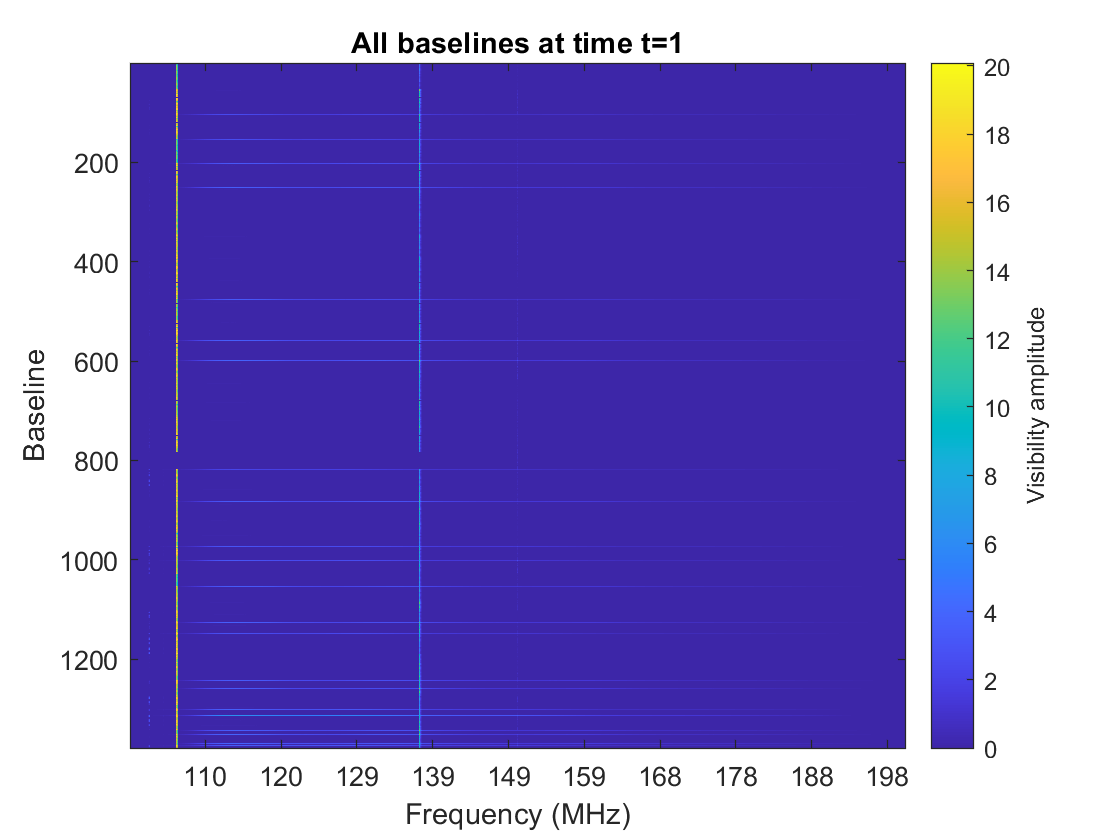

%Use just XX polarized light, as it has the highest magnitude of visibility
pol = 1;
range = 1:1378;
visdata_re = visdata.r(pol, :, 1, range);
visdata_im = visdata.i(pol, :, 1, range);
visdata_magnitude = sqrt(visdata_re.^2 + visdata_im.^2);
visdata_time1 = sum(visdata_magnitude(:, :, 1, range), 1)./4;

clf;
imagesc(squeeze(visdata_time1)')
xt = get(gca, 'XTick');
set(gca, 'XTick', xt, 'XTickLabel', round(xt/10.24 + 100));
xlabel('Frequency (MHz)');
ylabel('Baseline')
c = colorbar;
c.Label.String = "Visibility amplitude";
title('All baselines at time t=1')

We can remove these horizontal streaks of data, which correspond to baselines comprised of one antenna being correlated with itself.

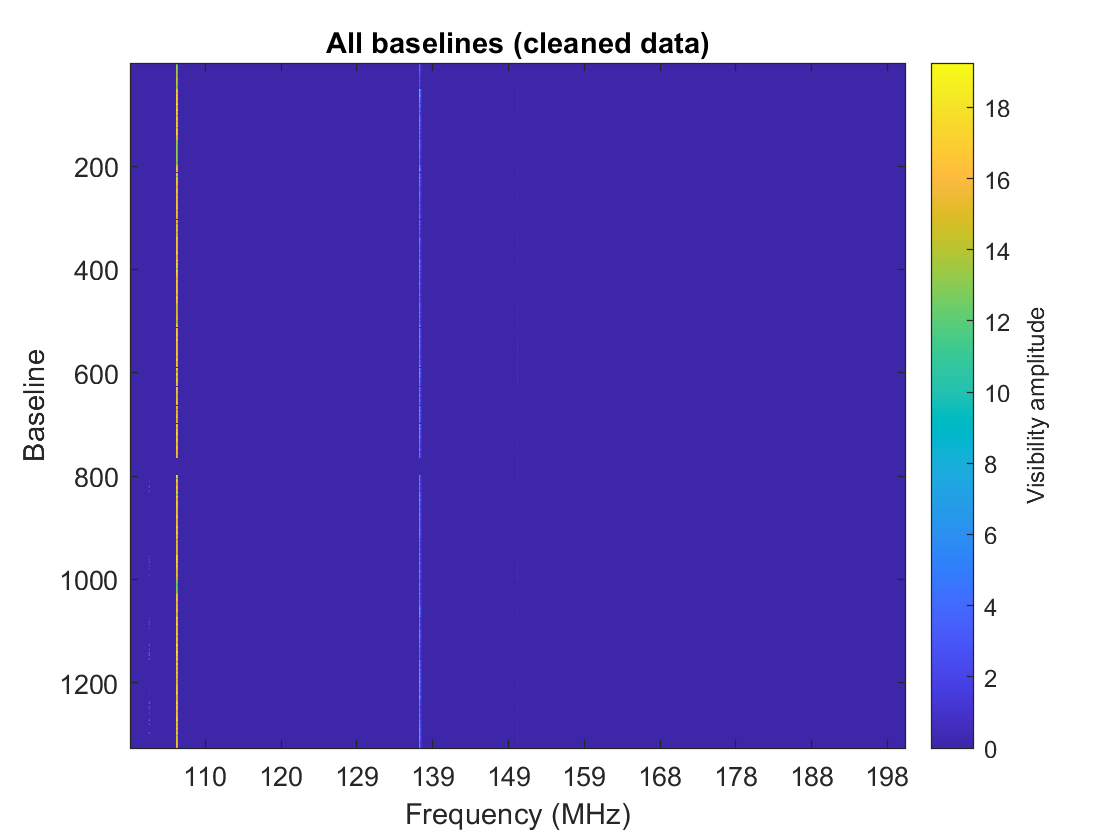

commonpair_indices = baselines(:, 1) == baselines(:, 2);
clean_data = visdata_time1(:, :, :, ~commonpair_indices);
clean_img = squeeze(clean_data)';
clf;
imagesc(clean_img);
xt = get(gca, 'XTick');
set(gca, 'XTick', xt, 'XTickLabel', round(xt/10.24 + 100));
xlabel('Frequency (MHz)');
ylabel('Baseline')
c = colorbar;
c.Label.String = "Visibility amplitude";
title('All baselines (cleaned data)')

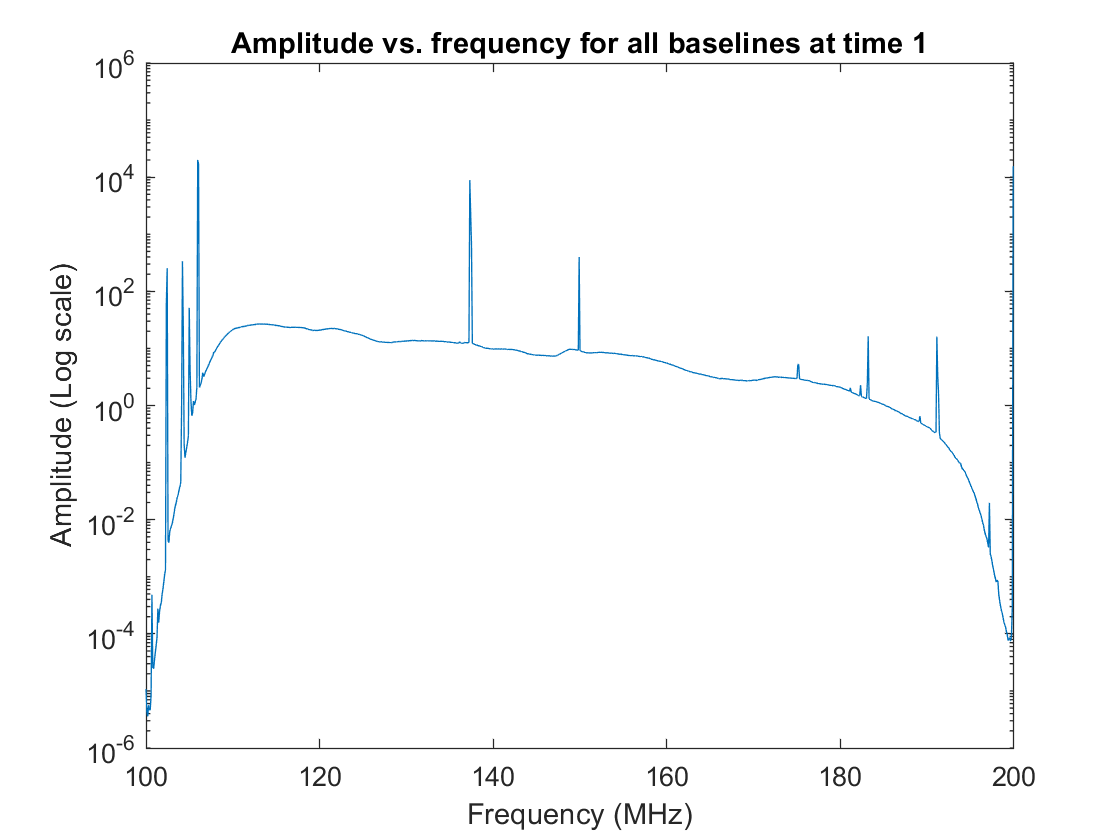

amplitude1 = squeeze(sum(clean_img, 1));
clf;
semilogy(freq_array ./ 1e6, amplitude1(1:1024))
xlabel('Frequency (MHz)');
ylabel('Amplitude (Log scale)')
title('Amplitude vs. frequency for all baselines at time 1')

The region of the most steady background is the flat middle region of this plot, ranging from indices ~180 to ~800 in the array of frequencies.

%Answers in MHz
freq_i = freq_array(180) ./ 1e6

freq_i = 117.4805

freq_f = freq_array(800) ./ 1e6

freq_f = 178.0273

We would like to fit a statistical model to a histogram of our data. This will help us analyze the overall trend of the data and predict the significance of certain signal strengths.

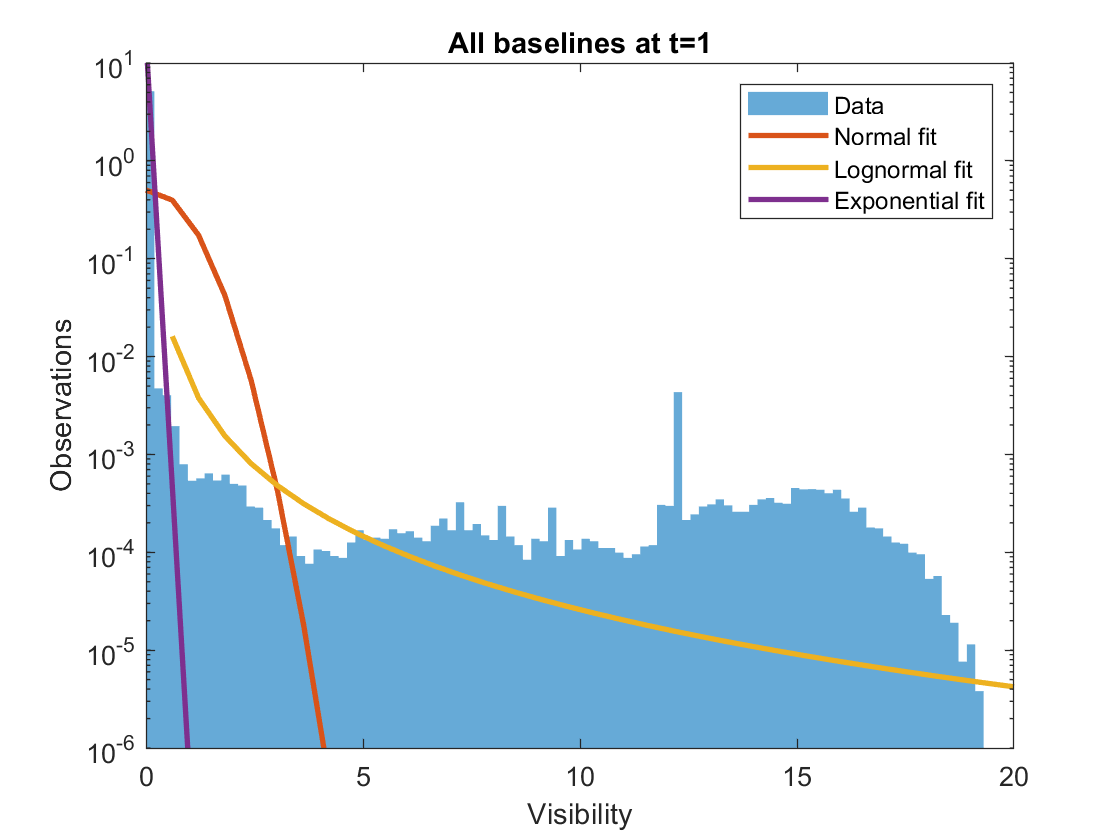

clf;
histogram(clean_img, 100, 'EdgeColor',"none", 'Normalization', 'pdf'), hold on;
clean_img_v = reshape(clean_img(clean_img > 0), 1, [])';

PDnorm = fitdist(clean_img_v, 'Normal');
PDlogn = fitdist(clean_img_v, 'Lognormal');
PDexp = fitdist(clean_img_v, 'Exponential');

xs = linspace(0, 60, 100);
norm_ys = normpdf(xs, PDnorm.mu, PDnorm.sigma);
logn_ys = lognpdf(xs, PDlogn.mu, PDlogn.sigma);
exp_ys = exppdf(xs, PDexp.mu);
plot(xs, [norm_ys; logn_ys; exp_ys], 'linewidth', 2);
set(gca, 'YScale', 'log')
xlim([0 20])
ylim([1e-6, 10])
ylabel('Observations')
xlabel('Visibility')
title('All baselines at t=1')
legend('Data', 'Normal fit', 'Lognormal fit', 'Exponential fit')

Unfortunately, it seems that no particular model would accurately fit to our data. Above are three examples of possible distributions which have their parameters set to most accurately fit the data as determined by MATLAB. In reality, this data is far too unpredictable and noisy to be described by a single statistical distribution.

By limiting the background data we look at, we can observe the trend for a subset of the data above. We can cut out the highly-varying data at the extreme ends of the frequency spectra. By doing this, we limit ourselves to look at data from the semi-stable region of background observed in the plot above of amplitude vs. frequency. Furthermore, we can limit ourselves to look at very low visibility amplitudes, since the spikes on the amplitude plot (likely corresponding to frequencies used for Earth-space communications) are anomalies that we can define and filter out.

clf;
clean_img_limited = clean_img(:, 180:800);
cap = 0.2;
bkg = clean_img_limited(clean_img_limited < cap);
histogram(bkg, 70, 'EdgeColor',"none", 'Normalization', 'pdf'), hold on;
bkg_v = reshape(bkg(bkg > 0), 1, [])';

PDlogn = fitdist(bkg_v, 'Lognormal')

PDlogn =   LognormalDistribution

  Lognormal distribution
       mu = -5.42747   [-5.42997, -5.42497]
    sigma =  1.15401   [1.15225, 1.15578]


PDexp = fitdist(bkg_v, 'Exponential')

PDexp =   ExponentialDistribution

  Exponential distribution
    mu = 0.00718246   [0.00716693, 0.00719804]


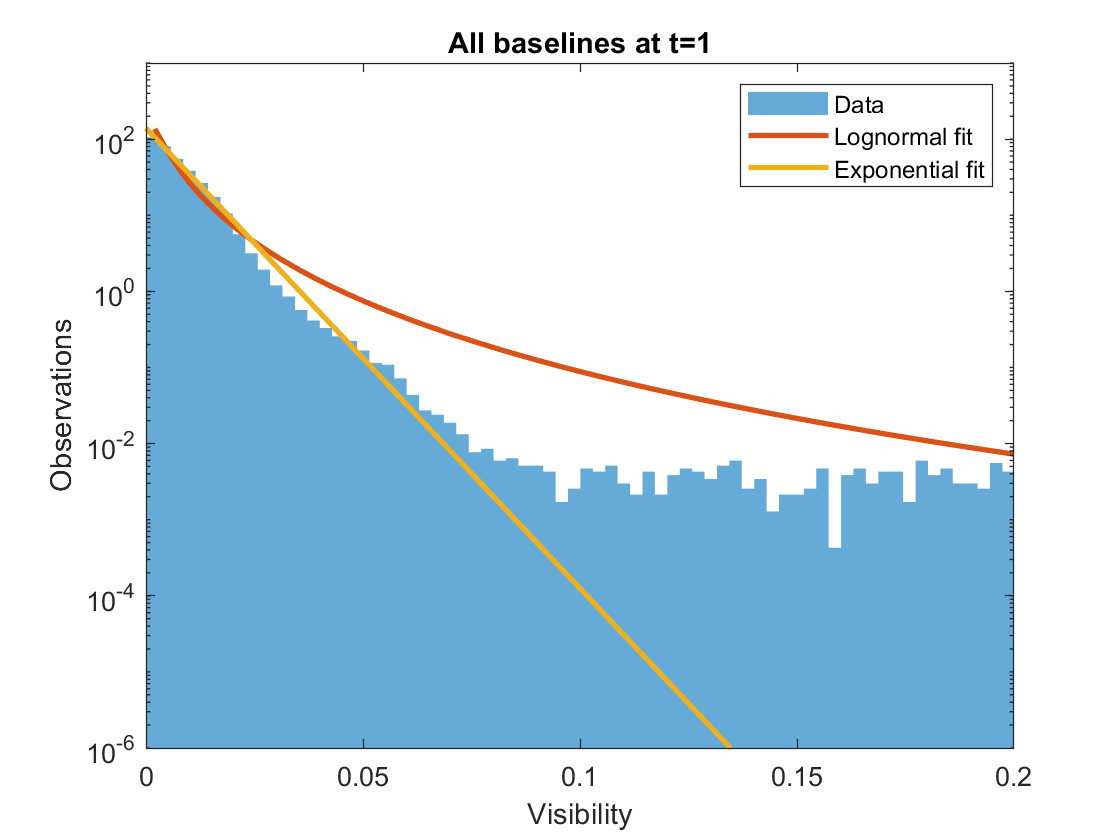


xs = linspace(0, cap, 100);
logn_ys = lognpdf(xs, PDlogn.mu, PDlogn.sigma);
exp_ys = exppdf(xs, PDexp.mu);
plot(xs, [logn_ys; exp_ys], 'linewidth', 2);
set(gca, 'YScale', 'log')
xlim([0 cap])
ylim([1e-6, 1e3])
ylabel('Observations')
xlabel('Visibility')
title('All baselines at t=1')
legend('Data', 'Lognormal fit', 'Exponential fit')

Now the background data seems to follow a lognormal trend. (The normal fit was removed for simplicity, and the exponential fit does not account for the concave nature of the plot.)

Using this data, we can now find the signal strength needed for an event with 5 sigma significance:

p_norm = normcdf(-5, 0, 1)

p_norm = 2.8665e-07

mu = PDlogn.mu;
sigma = PDlogn.sigma;
threshold = icdf('Lognormal', 1-p_norm, mu, sigma)

threshold = 1.4086

A visibility amplitude of 0.4247 is large enough to be a 5-sigma event. Note that this threshold is highly dependent on the parameters of the lognormal fit, and that slight variations of these parameters will yield very different thresholds for significant events.

### Problem 2

Now we will "inject" a signal into our background data and see what we observe. To do this, we will change random data points from the background distribution (about 10% of the points) to "signal strength", a strength of around 8 sigma. 

indices = (randi(10, [1, length(bkg)]) < 2);
p_norm = normcdf(-8, 0, 1)

p_norm = 6.2210e-16

signal1 = icdf('Lognormal', 1-p_norm, mu, sigma)

signal1 = 44.4732

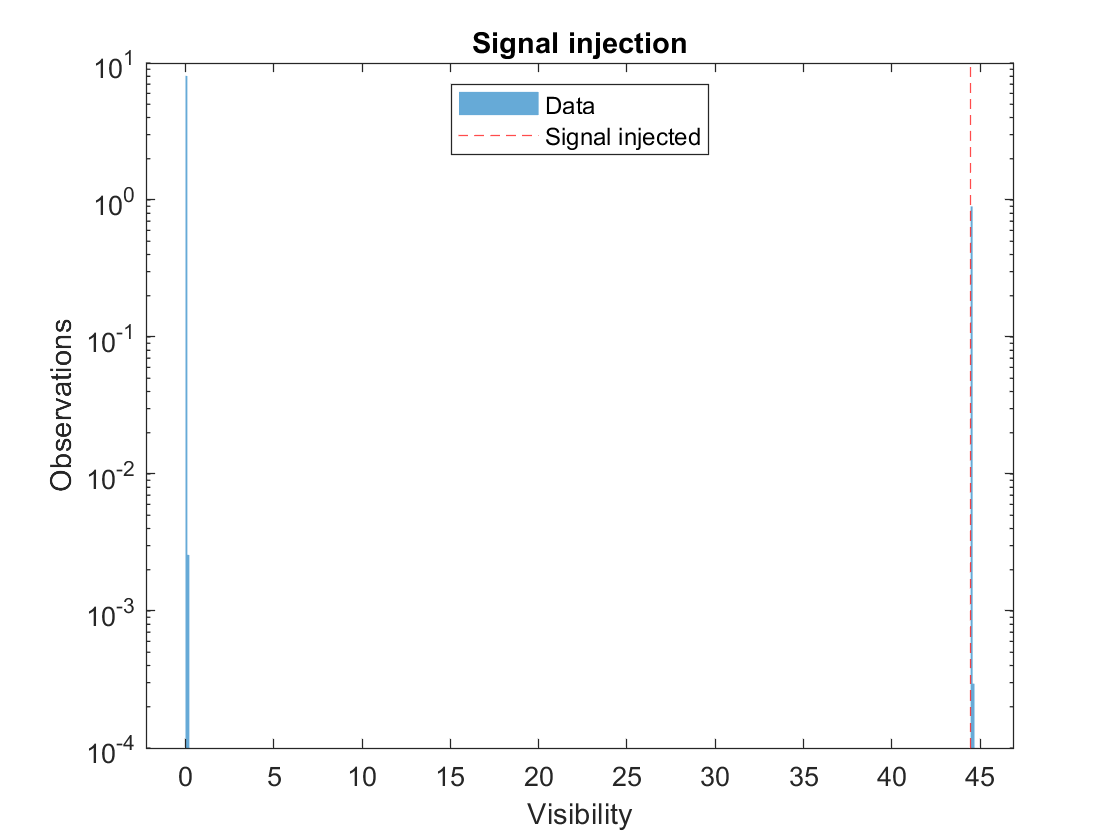

signal_injection = signal1 .* indices;

clf;
histogram(bkg' + signal_injection, 400, 'EdgeColor',"none", 'Normalization', 'pdf'), hold on;
xline(signal1, 'r--');
set(gca, 'YScale', 'log')
ylabel('Observations')
xlabel('Visibility')
title('Signal injection')
legend('Data', 'Signal injected', 'location', 'north')

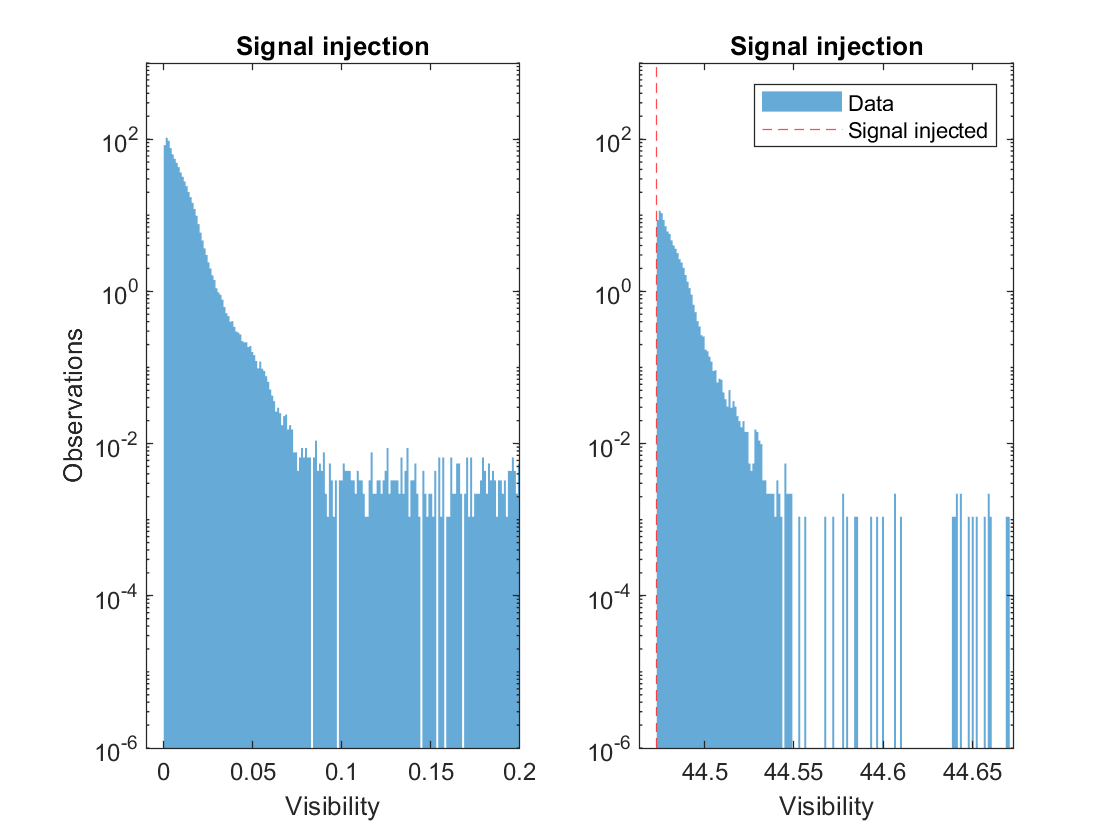

clf;
subplot(1, 2, 1);
histogram(bkg' + signal_injection, 40000, 'EdgeColor',"none", 'Normalization', 'pdf'), hold on;
xline(signal1, 'r--');
set(gca, 'YScale', 'log')
ylabel('Observations')
xlabel('Visibility')
title('Signal injection')
xlim([-0.01, 0.2])
ylim([1e-6, 1e3])

subplot(1, 2, 2);
histogram(bkg' + signal_injection, 40000, 'EdgeColor',"none", 'Normalization', 'pdf'), hold on;
xline(signal1, 'r--');
set(gca, 'YScale', 'log')
xlabel('Visibility')
title('Signal injection')
legend('Data', 'Signal injected')
xlim([signal1-0.01, signal1 + 0.2])
ylim([1e-6, 1e3])

The original background distribution can be seen on the left, ranging from 0 to 0.2. However, we now see an additional distribution on the right, which appears to be very similar to the original distribution. Both distributions are skewed to the right; this is a result of the original distribution being skewed to the right, where the background was more likely to be very small visibility amplitudes.

This makes sense; if we take a random sample of points from the original distribution and scale them up by a constant number, we will get two distributions with smaller amplitudes. By plotting these distributions on a linear scale, we can see that the new distribution is ~10% as large as the original distribution:

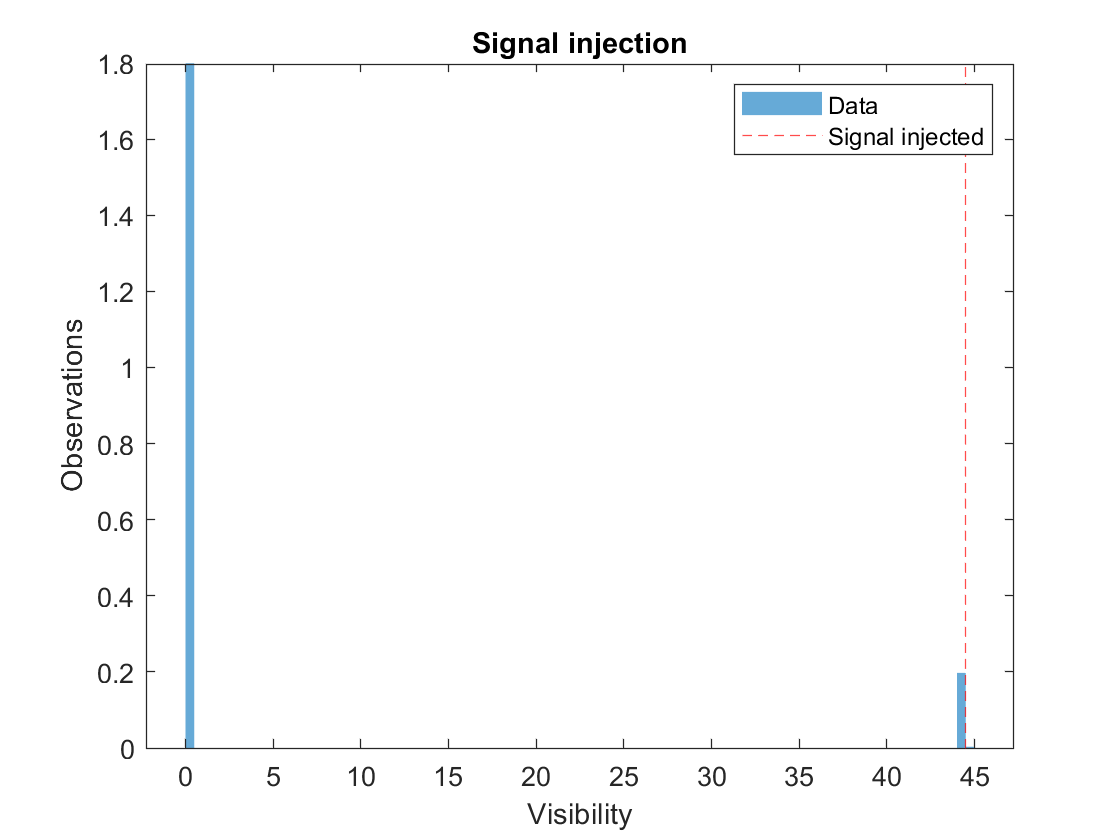

clf;
histogram(bkg' + signal_injection, 'EdgeColor',"none", 'Normalization', 'pdf'), hold on;
xline(signal1, 'r--');
ylabel('Observations')
xlabel('Visibility')
title('Signal injection')
legend('Data', 'Signal injected')

This distribution (involving both peaks) is skewed towards the left; there is more data to the left side of the full distribution. This is a result of the amount of signal we injected; since we only inject signal into 10% of the data points, 90% of the data is still part of the original distribution on the left hand side. If we increase this rate of injection to 70%:

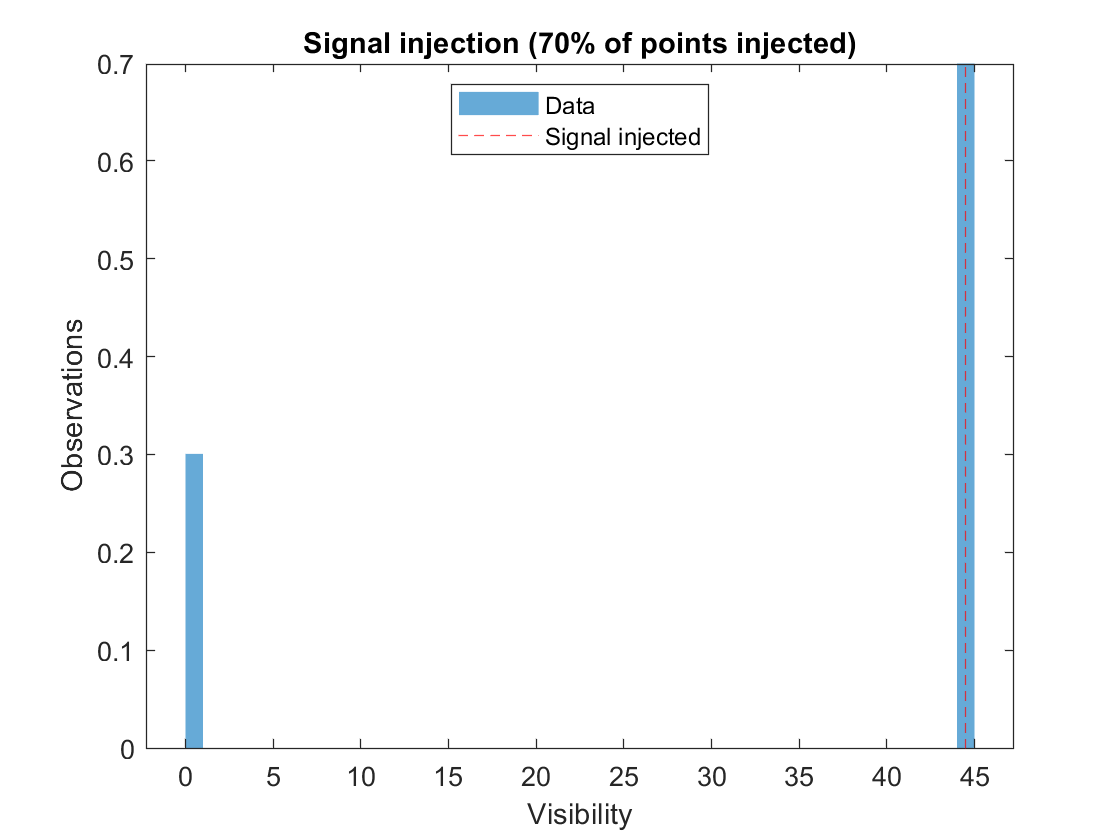

indices = (randi(10, [1, length(bkg)]) < 8);
%Same signal strength
signal_injection = signal1 .* indices;

clf;
histogram(bkg' + signal_injection, 'EdgeColor',"none", 'Normalization', 'pdf'), hold on;
xline(signal1, 'r--');
ylabel('Observations')
xlabel('Visibility')
title('Signal injection (70% of points injected)')
legend('Data', 'Signal injected', 'location', 'north')

Now the data is biased towards the right; it is more likely to observe the injected signal.

### Problem 3

Now we would like to observe what happens when we observe a range of different signal strengths into the background. By doing this, we are simulating measurements of data where we observe a particular strength of signal. Again, we will insert the signal to about 10% of the data points of the background distribution:

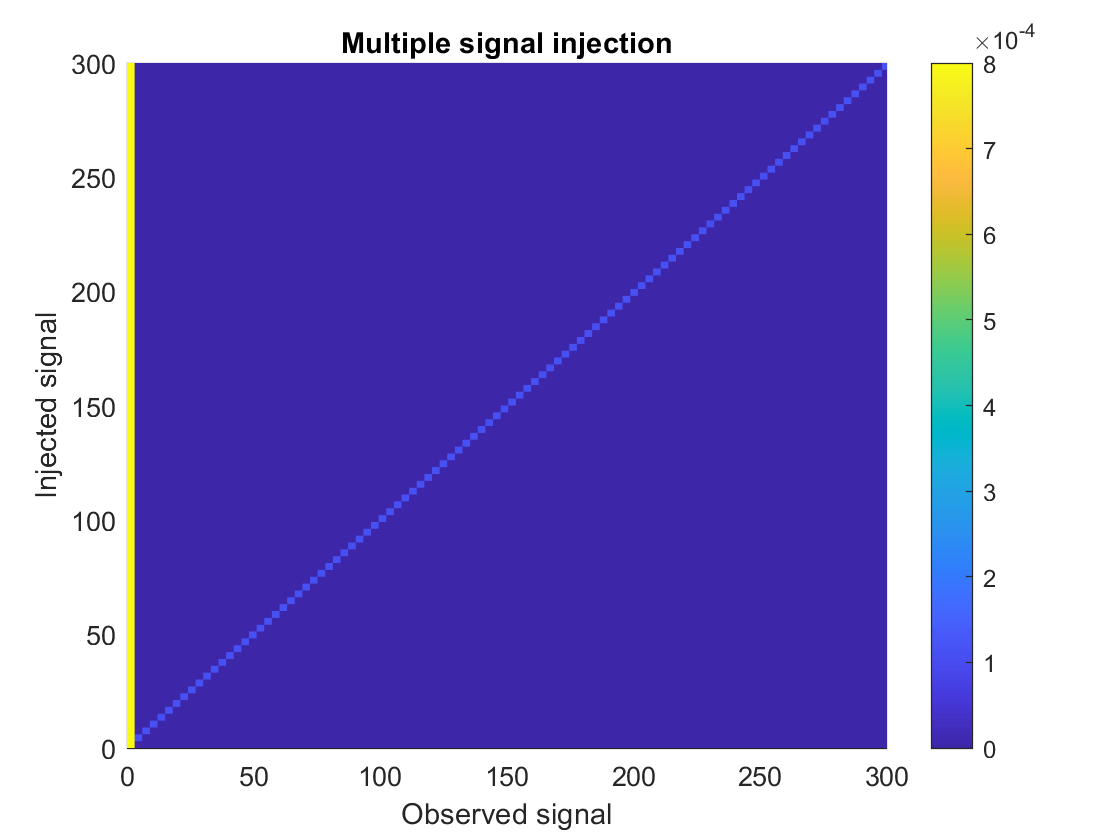

signal_lim = 300;
num_signals = 200;
bkg_sample = bkg(1:16:end);
l = length(bkg_sample);
signal_suite = linspace(0, signal_lim, num_signals);
indices = (randi(10, [num_signals, l]) < 2)';
[~, signal_array] = meshgrid(ones(1, l), signal_suite);

signals = signal_array' .* indices;
[~, bkg_array] = meshgrid(ones(1, num_signals), bkg_sample);
obssignal = bkg_array + signals;

clf;
h = histogram2(obssignal, signal_array', 100,'DisplayStyle','tile','ShowEmptyBins','on', 'Normalization', 'pdf');
xlabel('Observed signal');
ylabel('Injected signal');
axis([0 signal_lim 0 signal_lim])
c = colorbar;
title('Multiple signal injection')
caxis([0 8e-4])

Here we see a blue angled line which represents an approximately linear relationship between the strength of the injected signal and the strength of the observed signal. We also see a bright yellow line at the left edge of the plot; this represents our original background distribution. Just as before, when we inject a signal of a certain strength into our background, we obtain two seperate regions in the resulting distribution: one corresponding to the location of the original distribution, and one which begins at roughly the value of the injected signal. One can see, then, that this is a representation of several histograms of background distributions stacked vertically, with each row corresponding to a different injected signal strength.

Furthermore, if we increase the signal injection rate, then the diagonal line should become brighter, and the vertical line on the left edge of the plot should become dimmer, as the distribution on the right was brighter than the distribution on the left as in problem 2:

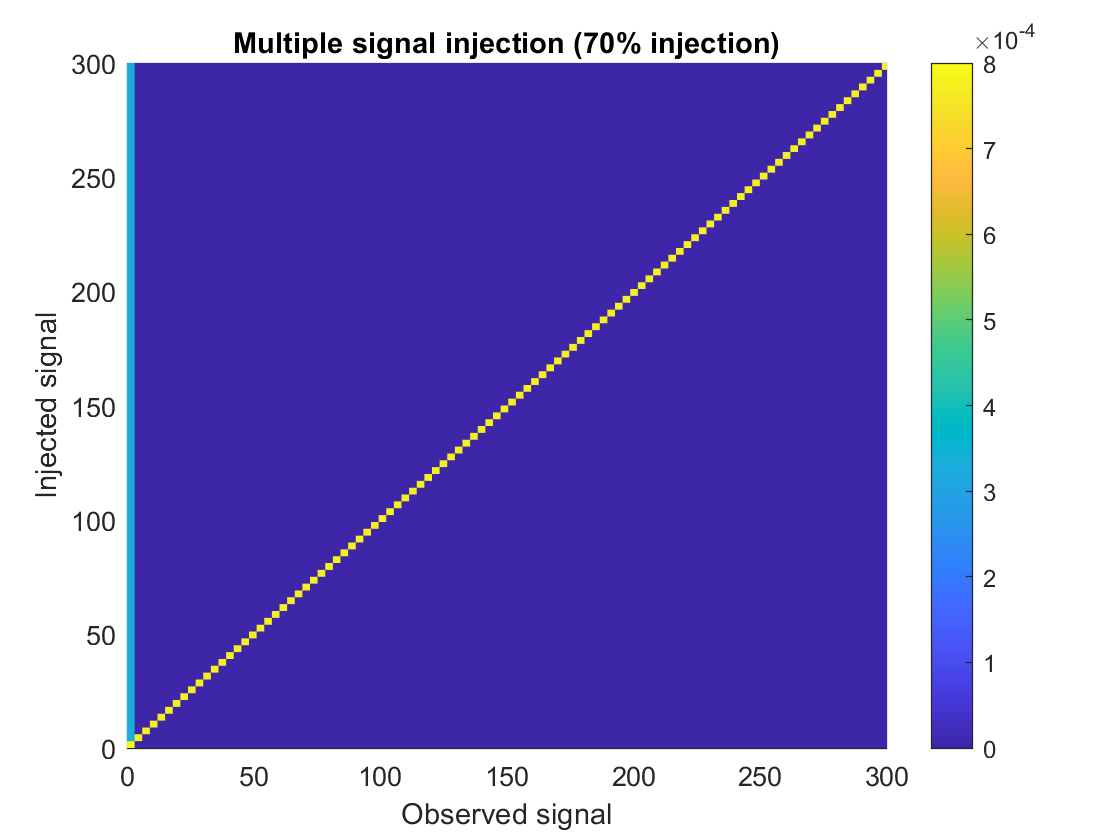

indices = (randi(10, [num_signals, l]) < 8)';
signals = signal_array' .* indices;
[~, bkg_array] = meshgrid(ones(1, num_signals), bkg_sample);
obssignal = bkg_array + signals;

clf;
h = histogram2(obssignal, signal_array', 100,'DisplayStyle','tile','ShowEmptyBins','on', 'Normalization', 'pdf');
xlabel('Observed signal');
ylabel('Injected signal');
axis([0 signal_lim 0 signal_lim])
c = colorbar;
title('Multiple signal injection (70% injection)')
caxis([0, 8e-4])

In this case, if we choose the same signal strength as in **Problem 2**, we should observe the same answer:

signal_lim = 300;
num_signals = 200;
bkg_sample = bkg(1:16:end);
l = length(bkg_sample);
signal_suite = linspace(0, signal_lim, num_signals);
indices = (randi(10, [num_signals, l]) < 2)';
[~, signal_array] = meshgrid(ones(1, l), signal_suite);

signal = signal1;

signals = signal_array' .* indices;
[~, bkg_array] = meshgrid(ones(1, num_signals), bkg_sample);
obssignal = bkg_array + signals;
%Find the value of injected signal which is the closest to the one we used in problem 2
[minval, ind] = min(abs(signal_suite - signal))

minval = 0.7529

ind = 31

p2_injected_signal = signal_suite(ind)

p2_injected_signal = 45.2261

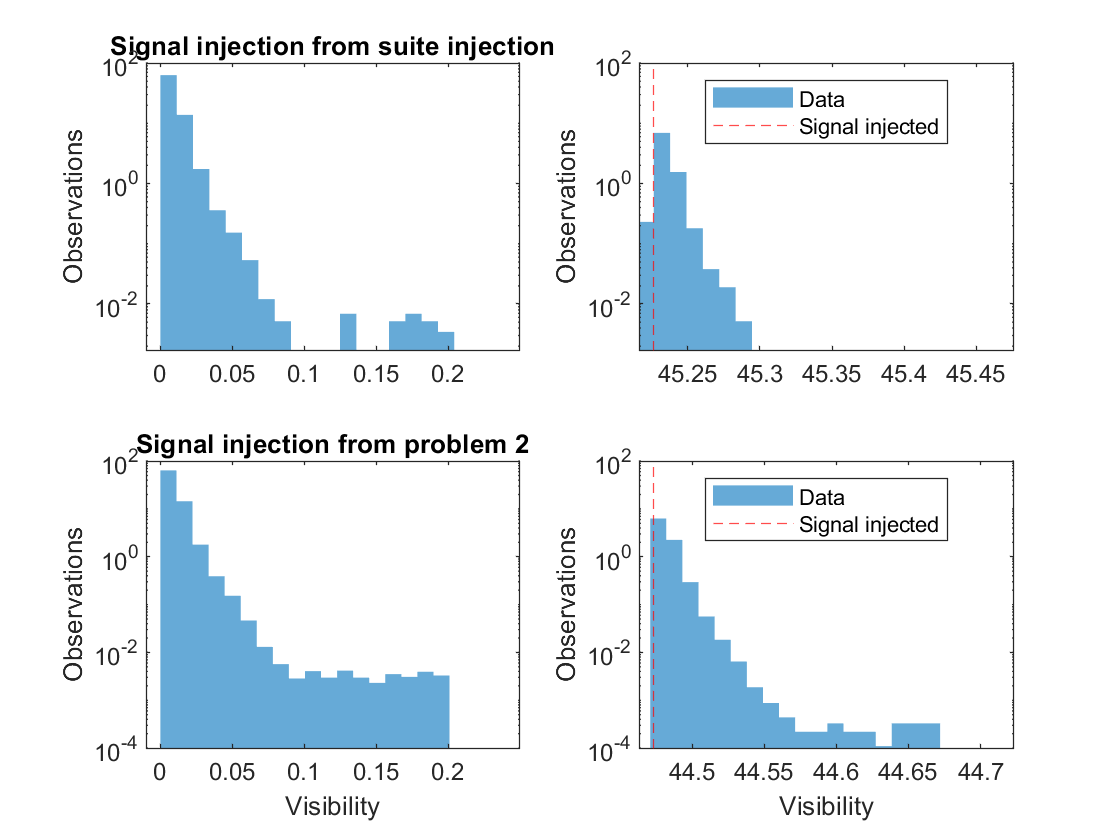

clf;

nbins = 4000;

subplot(2, 2, 1)
histogram(obssignal(:, ind),  nbins, 'EdgeColor',"none", 'Normalization', 'pdf'), hold on;
ylabel('Observations')
title('Signal injection from suite injection')
set(gca, 'YScale', 'log')
xlim([-0.01 0.25])

subplot(2, 2, 2)
histogram(obssignal(:, ind),  nbins, 'EdgeColor',"none", 'Normalization', 'pdf'), hold on;
xline(p2_injected_signal, 'r--');
ylabel('Observations')
set(gca, 'YScale', 'log')
legend('Data', 'Signal injected', 'location', 'north')
xlim([p2_injected_signal-0.01 p2_injected_signal+0.25])

indices = (randi(10, [1, length(bkg)]) < 2);
signal_injection = signal1 .* indices;

subplot(2, 2, 3)

histogram(bkg' + signal_injection, nbins, 'EdgeColor',"none", 'Normalization', 'pdf'), hold on;
set(gca, 'YScale', 'log')
ylabel('Observations')
xlabel('Visibility')
title('Signal injection from problem 2')
xlim([-0.01 0.25])

subplot(2, 2, 4)
histogram(bkg' + signal_injection, nbins, 'EdgeColor',"none", 'Normalization', 'pdf'), hold on;
xline(signal1, 'r--');
set(gca, 'YScale', 'log')
ylabel('Observations')
xlabel('Visibility')
legend('Data', 'Signal injected', 'location', 'north')
xlim([signal-0.01 signal+0.25])

3.c)

Now, to reverse the problem, let us choose a value of **observed signal** and create a histogram of possible **injected signals** for that observation.

obs_signal = 80

obs_signal = 80

Our 2-D histogram has the array of signals on the y-axis, so we can use the values from this array corresponding to our observed signal for our histogram.

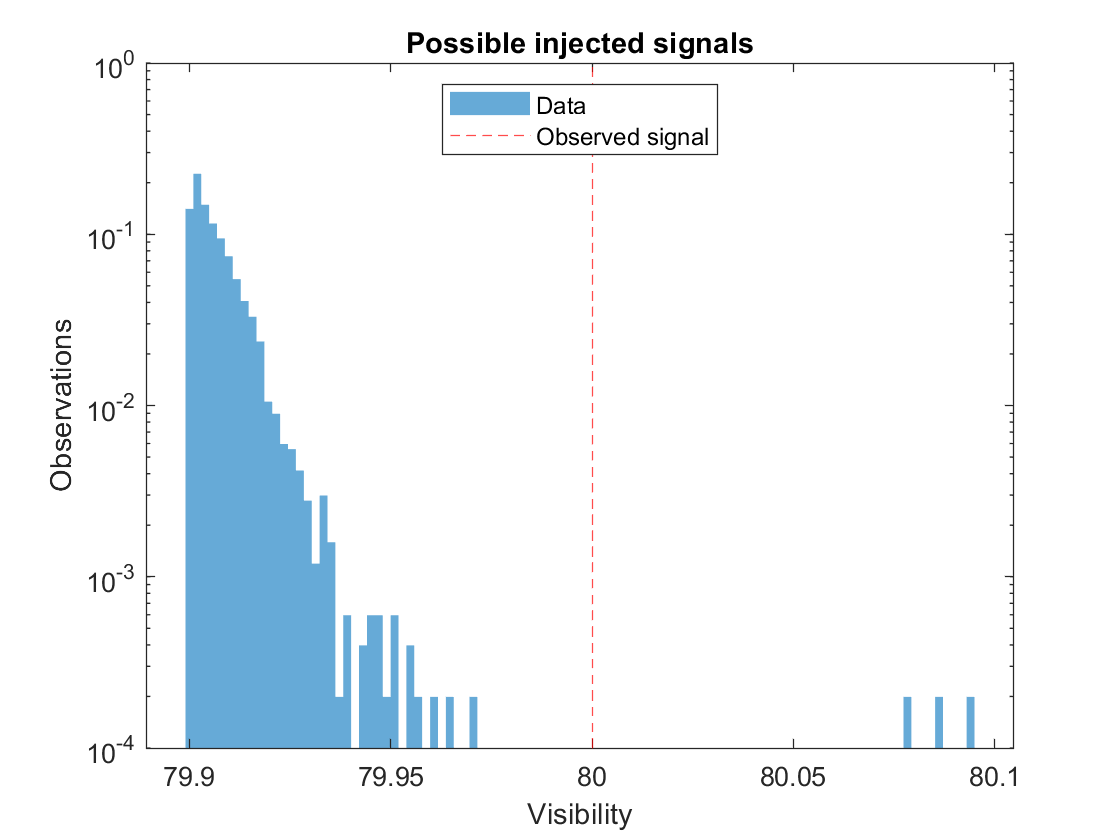

locs = abs(obssignal - obs_signal) < 0.2;
injected_candidates = obssignal((obssignal .* locs) > 0);
clf;
histogram(injected_candidates, 100, 'EdgeColor',"none", 'Normalization', 'probability'), hold on;
xline(obs_signal, 'r--');
set(gca, 'YScale', 'log')
ylabel('Observations')
xlabel('Visibility')
%xlim([7.82, 8.12])
title('Possible injected signals')
legend('Data', 'Observed signal', 'location', 'north')

This distribution looks very similar to our original background distributon. Recall that injecting a signal of a certain value yields two regions in a distribution: one corresponding to the original background, and one corresponding to the injected signal. The distribution *should* be mirrored about the x-axis, however-this is because we are making a histogram of one vertical column of the 2d histogram above. This implies that the injected signal should be less than the observed signal, which is still true given the histogram above.

We know that only one specific value was injected to produce this distribution. We would like to find out the 1 sigma uncertainty on this value. To do this, we can sum the probabilities associated with each bin in our histogram until we reach the probability of a 1-sigma event on the stndard normal distribution.

uncertainty1 = normpdf(1, 0, 1)

uncertainty1 = 0.2420

clear probs bins;
[counts, bins] = hist(injected_candidates, 100, 'EdgeColor',"none", 'Normalization', 'probability');
probs = counts ./ length(injected_candidates);
p_sum = 0;
while p_sum < uncertainty1
    p_sum = p_sum + probs(end);
    probs(end) = [];
    bin = bins(end);
    bins(end) = [];
end
p_sum

p_sum = 0.2566

uncertainty_interval = obs_signal - bin

uncertainty_interval = 0.0898

Therefore, the true value of the injected signal is, to within 1 sigma of confidence, within 0.0902 of the observed signal.

### Problem 4

We can repeat this same process using a very weak signal of about 1 sigma.

p_norm_1 = normpdf(-1, 0, 1)

p_norm_1 = 0.2420

obs_signal = icdf('Lognormal', 1-p_norm_1, -5.4275, 1.15)

obs_signal = 0.0098

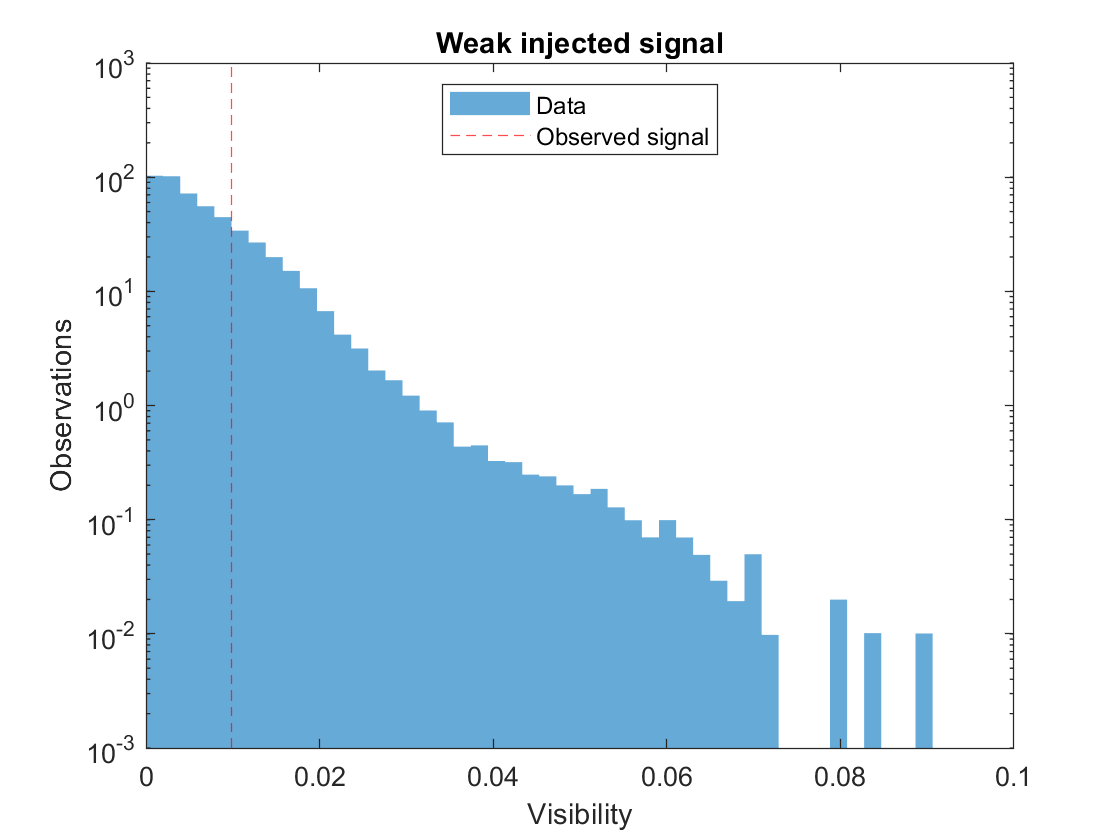

locs = abs(obssignal - obs_signal) < 0.2;
injected_candidates = obssignal((obssignal .* locs) > 0);

clf;
histogram(injected_candidates, 100, 'EdgeColor',"none", 'Normalization', 'pdf'), hold on;
xline(obs_signal, 'r--');
set(gca, 'YScale', 'log')
ylabel('Observations')
xlabel('Visibility')
xlim([0, 0.1])
title('Weak injected signal')
legend('Data', 'Observed signal', 'location', 'north')

Now that our injected signal is well within our original background distribution, it is hard to tell the two sections of the full distribution apart, since they now overlap. As a result, the full distribution now extends all the way to zero rather than having a large gap between the two sections. This means that there is a possibility that there was *no* injected signal at all, and that we observe the original background distribution.

To find the 95% confidence interval for this distribution, we follow a similar method as before:

cl95 = 0.95

cl95 = 0.9500

clear probs bins;
[counts, bins] = hist(injected_candidates, 100, 'EdgeColor',"none", 'Normalization', 'probability');
probs = counts ./ length(injected_candidates);
p_sum = 0;
while p_sum < cl95
    p_sum = p_sum + probs(end);
    probs(end) = [];
    bin = bins(end);
    bins(end) = [];
end
p_sum

p_sum = 1

uncertainty_interval = obs_signal - bin

uncertainty_interval = 0.0088

The 95% confidence interval for this signal is within 0.0088 of the observed signal. In other words, if we observe a signal of strength 0.0098, the true injected signal will be less than 0.0098 95% of the time.